clear; clc; close all;

%% Load uncertain plant model
quanser_aero_parameters;
quanser_aero_state_space;

G_unc = ss(A, B, C, D);        % uncertain plant
G_nom = G_unc.NominalValue;   % nominal for synthesis

%% Define weights
s = tf('s');
wc = 5;        % crossover freq
M = 3;         % sensitivity peak
A = 1/1000;    % low-frequency disturbance rejection

Wp_single = (s/M + wc) / (s + wc*A);
Wp = blkdiag(Wp_single, Wp_single);
Wu = 0.01 * eye(2);  % constant control weight

%% Generalized plant for H∞ synthesis
P = augw(G_nom, Wp, Wu);

%% H∞ synthesis
[K_hinf, CL_hinf, gam_hinf] = hinfsyn(P, 2, 2);
disp("H∞ optimal gamma: " + gam_hinf);

H∞ optimal gamma: 1.8022


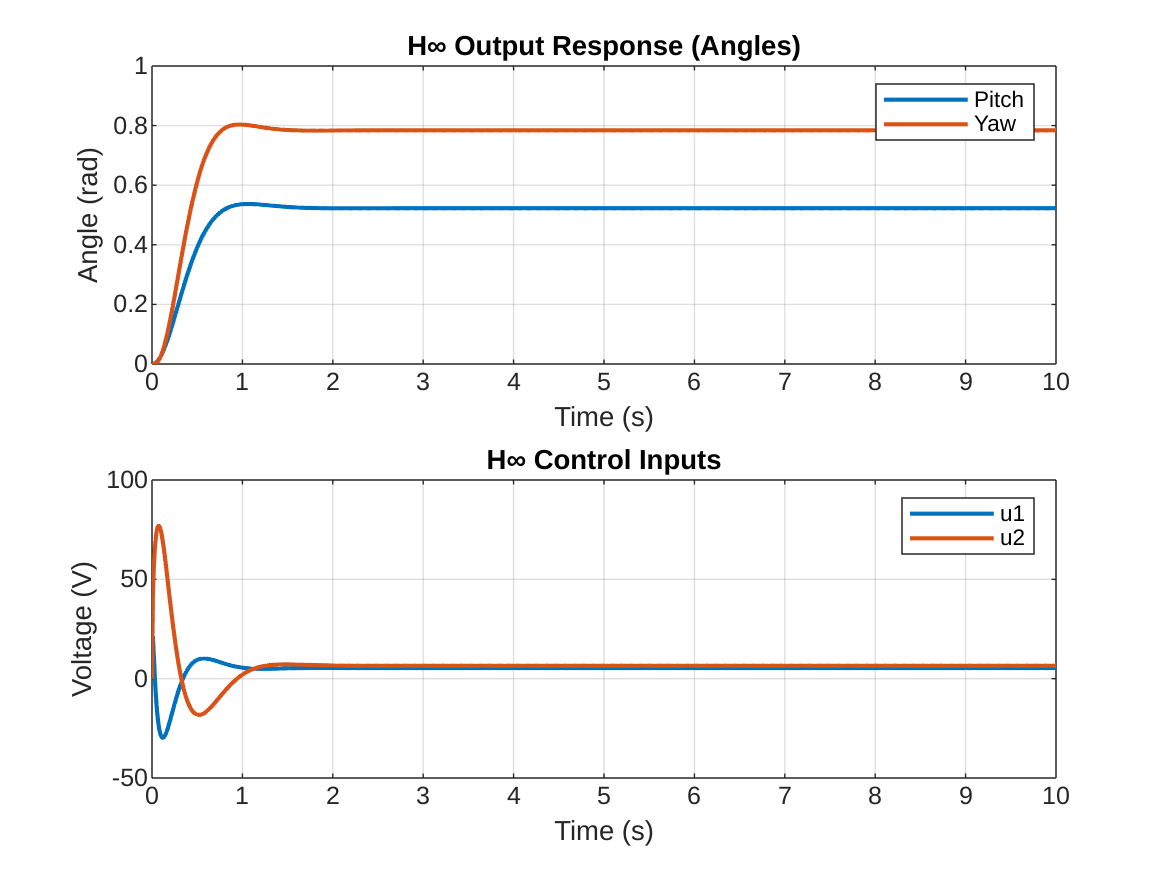


%% Closed-loop from r to y
T = feedback(G_nom * K_hinf, eye(2));

%% Simulate tracking
t = 0:0.01:10;
r = [pi/6 * ones(length(t),1), pi/4 * ones(length(t),1)];
[y, ~] = lsim(T, r, t);

% Compute control input: u = K * (r - y)
e = r - y;
u = lsim(K_hinf, e, t);

%% Plot outputs
figure;
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 1.5); hold on;
plot(t, y(:,2), 'LineWidth', 1.5);
title('H∞ Output Response (Angles)');
xlabel('Time (s)'); ylabel('Angle (rad)');
legend('Pitch','Yaw'); grid on;

%% Plot control inputs
subplot(2,1,2);
plot(t, u(:,1), 'LineWidth', 1.5); hold on;
plot(t, u(:,2), 'LineWidth', 1.5);
title('H∞ Control Inputs');
xlabel('Time (s)'); ylabel('Voltage (V)');
legend('u1','u2'); grid on;


%% === Robust Stability ===
CL_unc = feedback(G_unc * K_hinf, eye(2));
[stab_margin, stab_report] = robstab(CL_unc);
disp('--- Robust Stability ---');

--- Robust Stability ---


RS = 1 / stab_margin.LowerBound;
fprintf('Robust Stability Margin (RS) = %.4f\n', RS);

Robust Stability Margin (RS) = 0.2553




%% === Robust Performance ===
P_unc = augw(G_unc, Wp, Wu);
CL_perf = lft(P_unc, K_hinf);
[perf_margin, perf_report] = robustperf(CL_perf);
disp('--- Robust Performance ---');

--- Robust Performance ---


disp(perf_report);

    Jp: 0.0202
    Jy: 0.0237



RP = 1 / perf_margin.LowerBound;
fprintf('Robust Performance Margin (RP) = %.4f\n', RP);

Robust Performance Margin (RP) = 2.2448
